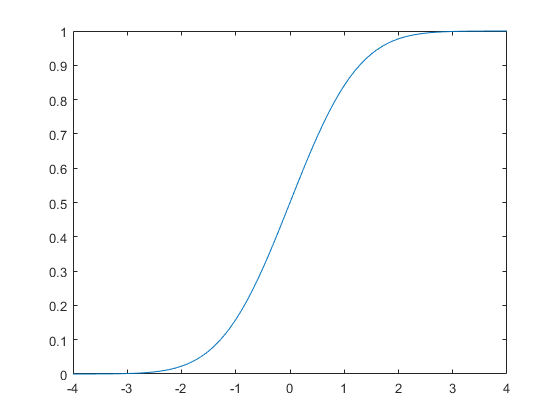

x = [-4:.1:4];
y = normcdf(x, 0, 1);
figure
plot(x,y)

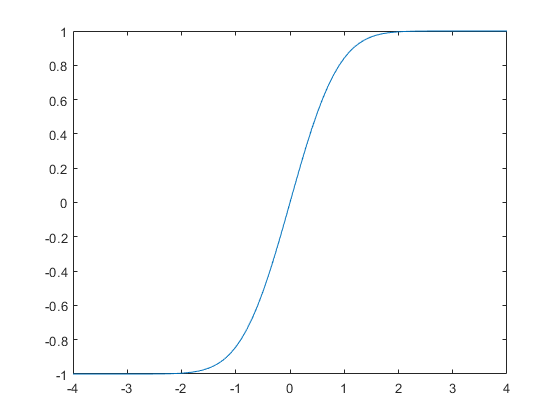

% hold on
plot(x, erf(x))


normcdf(1.5)

ans = 0.9332

normcdf(1.5)-normcdf(-0.5)

ans = 0.6247

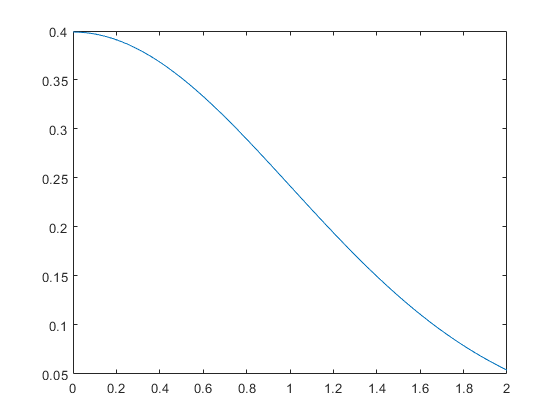

x = linspace(0,2);
fx = normpdf(x);
plot(x, fx)

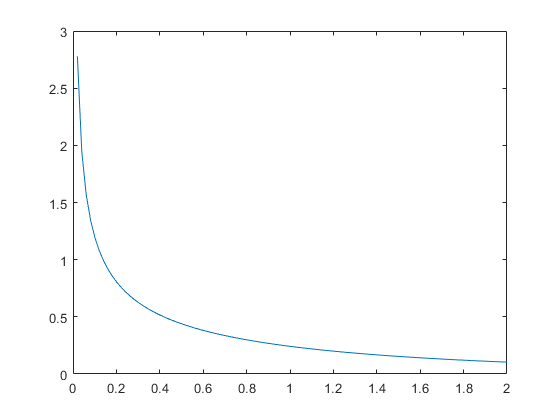

y = linspace(0,2);
fy = 1./sqrt(2*pi*y) .* exp(-y/2);
plot(y,fy)

k = [8:1:12];
p=0;
for i = k
    p = p + poisspdf(i,10);
end
p

p = 0.5713

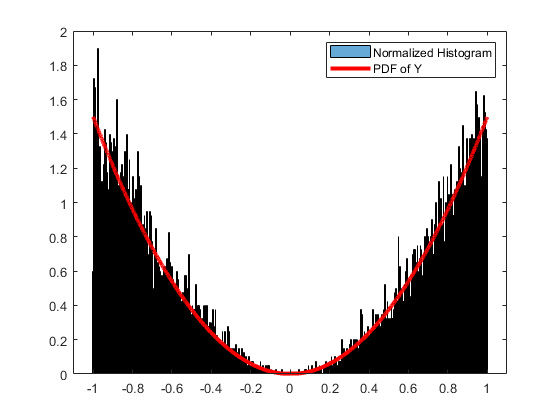

x = rand(1,10000);
y = sign(2*x-1).*abs((2*x-1).^(1/3));
figure
histogram(y, 500, 'Normalization',"pdf")
hold on
plot(sort(y), 3/2*sort(y).^2, 'r-','LineWidth',3)
legend('Normalized Histogram', 'PDF of Y')

x = rand(1,10000);
y = log(2*x)/4 .*(x<0.5) + (-log(2-2*x))/4 .*(x>0.5)

y =     0.2011    0.0032   -0.6116    0.0328   -0.0161    0.1545    0.0352    0.3577   -0.7968    0.2560   -0.0759   -0.1086    0.1212    0.2438   -0.0872    0.0156    0.5912    0.7379   -0.8631   -0.0405    0.2698    0.1250   -0.1017   -0.1335   -0.9004   -0.1864   -0.0173   -0.3256   -0.2088    0.2195   -0.0970   -0.1704    0.5117   -0.2732   -0.1040   -0.2352   -0.2504    0.5684    0.2326    0.1984   -0.2095    0.1892    0.0826    0.1667    0.1169    0.3046   -0.6942    0.0443   -0.1151   -0.2772


figure
histogram(y, 1000, 'Normalization',"pdf")
hold on
y = sort(y)

y =    -2.1757   -1.8334   -1.7641   -1.7570   -1.7412   -1.7189   -1.6123   -1.5940   -1.5859   -1.5808   -1.5795   -1.5764   -1.5108   -1.5006   -1.4813   -1.4804   -1.4376   -1.4327   -1.3910   -1.3662   -1.3609   -1.3564   -1.3349   -1.3331   -1.3274   -1.3208   -1.3136   -1.2997   -1.2916   -1.2647   -1.2646   -1.2618   -1.2488   -1.2474   -1.2447   -1.2356   -1.2339   -1.2333   -1.2304   -1.2280   -1.2268   -1.2243   -1.2207   -1.2205   -1.2191   -1.2179   -1.2162   -1.2157   -1.2073   -1.2052


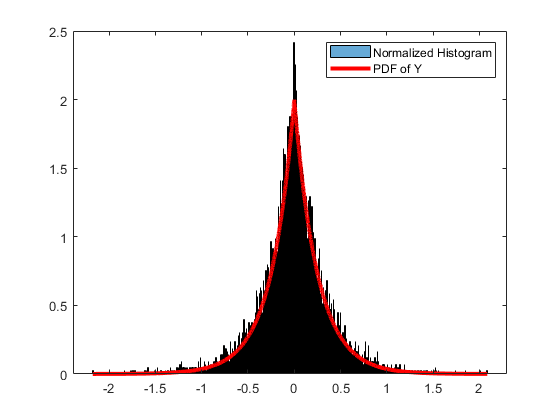

fy = 2*exp(-4*abs(y));
plot(y, fy, 'r-','LineWidth',3)
legend('Normalized Histogram', 'PDF of Y')

clear
lamb = roots([0.51, -1, 0.48, 0.01])

lamb =     1.0000
    0.9808
   -0.0200



A=[1, 1, 1; 1, 1/lamb(2), 1/lamb(3); 1, lamb(2)^200, lamb(3)^200]

A =     1.0000    1.0000    1.0000
    1.0000    1.0196  -50.0196
    1.0000    0.0206         0


a = inv(A)*[0, 0, 1]'

a =     1.0210
   -1.0206
   -0.0004


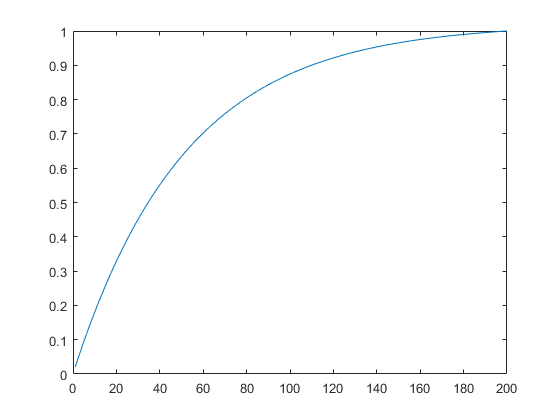

n = [1:1:200];
pn = a(1)*lamb(1).^n + a(2)*lamb(2).^n + a(3)*lamb(3).^n;
figure
plot(n, pn)

pn(100)

ans = 0.8745

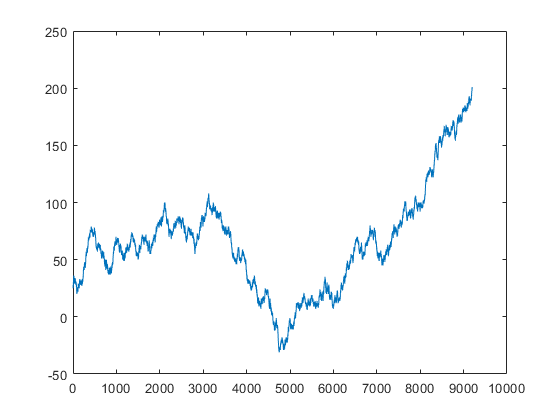

rand_num = rand(1, 10000);
p = [];
p(1) = 25;
for t = 1:10000
    if rand_num(t) < 0.51
       p(t+1) = p(t) + 1;
    elseif i > 0.99
       p(t+1) = p(t) - 2;
    else
       p(t+1) = p(t) - 1;
    end
    if p(t+1)>200
        break
    end
end

figure
plot(p)